a = 1+mod(137,3);

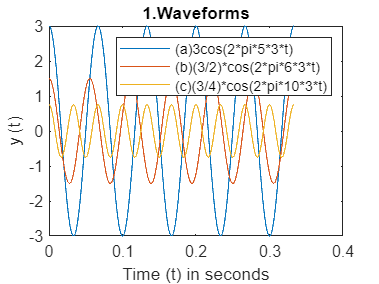

%Problem 1
%1)
t = [0:0.0001:1/a];
figure;
y1 = a*cos(2*pi*5*a*t);
y2 = (a/2)*cos(2*pi*6*a*t);
y3 = (a/4)*cos(2*pi*10*a*t);

plot(t, y1, t, y2, t, y3)
xlabel('Time (t) in seconds')
ylabel('y (t)')
title('1.Waveforms')
legend('(a)3cos(2*pi*5*3*t)','(b)(3/2)*cos(2*pi*6*3*t)','(c)(3/4)*cos(2*pi*10*3*t)');

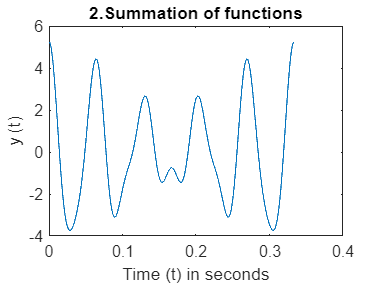

%2)
figure;
y = y1 + y2 + y3;
plot(t,y);
xlabel('Time (t) in seconds')
ylabel('y (t)')
title('2.Summation of functions')

%3)
figure;
x = (3 * 10)-1 %10 considering the max freq

x = 29

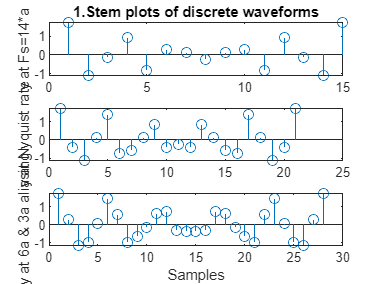

subplot(3,1,1);
%a 42Hz
Fs1 = 14 * a;
n2 = [0:1/Fs1:1/a];
y1 = a *cos(2*pi*5*a*n2);
y2 = a/2 *cos(2*pi*6*a*n2);
y3 = a/4 *cos(2*pi*10*a*n2);
y11 = y1 + y2 + y3;
stem(y11);
ylabel('y at Fs=14*a')
title('1.Stem plots of discrete waveforms')
subplot(3,1,2);
%b Nyquist rate => 2 * max freq => 2 * 10  *a =>20 * a 60 Hz.
Fs2 = 20 * a;
n2 = [0:1/Fs2:1/a];
y1 = a *cos(2*pi*5*a*n2);
y2 = a/2 *cos(2*pi*6*a*n2);
y3 = a/4 *cos(2*pi*10*a*n2);
y22 = y1 + y2 + y3;
stem(y22);
ylabel('y at Nyquist rate')
%plot 0 - len-1 , in samples
subplot(3,1,3);
% 6a aliased with 3a => 18Hz aliased with 9Hz => if Sampling freq is 18 + 9 =
% 27 Hz, 27/2 = 13.5 Hz So upon folding at 13.5, 18 overlaps 9.
Fs3 = 27;
n2 = [0:1/Fs3:1/a];
y1 = a *cos(2*pi*5*a*n2);
y2 = a/2 *cos(2*pi*6*a*n2);
y3 = a/4 *cos(2*pi*10*a*n2);
y33 = y1 + y2 + y3;
stem(y33);
ylabel('y at 6a & 3a aliasing')
xlabel('Samples')

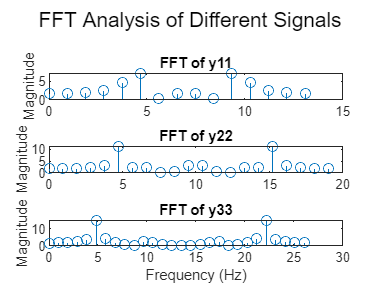

figure;

% Your existing code for the stem plots

% FFT of y11
fft_y11 = fft(y11);
frequencies_y11 = (0:length(fft_y11)-1) * (Fs1 / length(fft_y11));

% FFT of y22
fft_y22 = fft(y22);
frequencies_y22 = (0:length(fft_y22)-1) * (Fs2 / length(fft_y22));

% FFT of y33
fft_y33 = fft(y33);
frequencies_y33 = (0:length(fft_y33)-1) * (Fs3 / length(fft_y33));

% Plot FFTs
figure;
subplot(3, 1, 1);
stem(frequencies_y11, abs(fft_y11));
ylabel('Magnitude');
title('FFT of y11');

subplot(3, 1, 2);
stem(frequencies_y22, abs(fft_y22));
ylabel('Magnitude');
title('FFT of y22');

subplot(3, 1, 3);
stem(frequencies_y33, abs(fft_y33));
ylabel('Magnitude');
xlabel('Frequency (Hz)');
title('FFT of y33');

sgtitle('FFT Analysis of Different Signals');

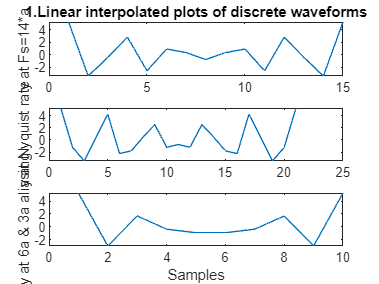

%4)
figure;
subplot(3,1,1);
plot(y11);
ylabel('y at Fs=14*a')
title('1.Linear interpolated plots of discrete waveforms')
subplot(3,1,2);
plot(y22);
ylabel('y at Nyquist rate')
subplot(3,1,3);
plot(y33);
ylabel('y at 6a & 3a aliasing')
xlabel('Samples')

%5)

%Problem 2)
s1 = sin(2*pi*240*t);
s2 = sin(2*pi*270*t);
s3 = sin(2*pi*300*t);
s4 = sin(2*pi*320*t);
s5 = sin(2*pi*360*t);
s6 = sin(2*pi*400*t);
s7 = sin(2*pi*450*t);
s8 = sin(2*pi*480*t);
s = [s1,s2,s3,s4,s5,s6,s7,s8];
audiowrite("Doremi_48000.wav",s,48000)

% sound(s,48000)
% sound(s,24000)
% sound(s,16000)
% sound(s,8000)
% sound(s,4000)

%increasing sampling rate increases both speed of the audio as well as
%loudness and pitch

% Define parameters
Fs = 1000; % Sampling frequency
t = 0:1/Fs:1; % Time values

% Generate individual sinusoidal components
s1 = sin(2 * pi * 240 * t);
s2 = sin(2 * pi * 270 * t);
s3 = sin(2 * pi * 300 * t);
s4 = sin(2 * pi * 320 * t);
s5 = sin(2 * pi * 360 * t);
s6 = sin(2 * pi * 400 * t);
s7 = sin(2 * pi * 450 * t);
s8 = sin(2 * pi * 480 * t);

% Combine the sinusoidal components
s = s1 + s2 + s3 + s4 + s5 + s6 + s7 + s8;

% Compute the FFT of the combined signal
fft_s = fft(s);
frequencies = (0:length(fft_s)-1) * (Fs / length(fft_s));

% Plot the original signal
figure;
subplot(2, 1, 1);
plot(t, s);
xlabel('Time');
ylabel('Amplitude');
title('Combined Sinusoidal Signal');

% Plot the FFT
subplot(2, 1, 2);
stem(frequencies, abs(fft_s));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('FFT of Combined Sinusoidal Signal');

sgtitle('FFT Analysis of Combined Sinusoidal Signal');


%Problem 3
[data,Fs] = audioread("Track003.wav")

data =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Fs = 48000

sound(data,Fs)
length(data)

ans = 816239

data2 = data(1:3:end, 1);
length(data2)

ans = 272080

sound(data2,Fs/3)

data3 = data(1:5:end, 1);
length(data3)

ans = 163248

sound(data2,Fs/5)
%higher frequencies seem absent as we increase the frequencies